Laborator 12 - Rezolvarea numerică a ecuațiilor neliniare

PROBLEME

P1. Implementați metodele Newton, secantă, Steffensen.

% Newton:
f = @(x) (cos(x) - x);
fd = @(x) (-sin(x) - 1);
x0 = 0.4;
[z, ni] = Newton(f, fd, x0);
fprintf("Metoda lui Newton:");

Metoda lui Newton:

fprintf("f(x) = cos(x) - x");

f(x) = cos(x) - x

fprintf("x = %f", z);

x = 0.739085

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 3


% Metoda secantei:
f = @(x) (cos(x) - x);
x1   = [0.5 0.4];
x2   = [pi/4 pi/5];
err  = eps;
nmax = 100;

[z, ni] = secant(f, x1, x2, err, nmax);
fprintf("Metoda secantei:");

Metoda secantei:

fprintf("f(x) = cos(x) - x");

f(x) = cos(x) - x

fprintf("x1 = %f, x2 = %f", z);

x1 = 0.797312, x2 = 0.640232

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 1


% Steffensen:
% f(x) = x^3 + 4x^2 - 10
g = @(x)sqrt(10 / (x + 4));
p0 = 1.5;
err = 0.0001;
nmax = 100;
p = Steffensen(g, p0, err, nmax);
fprintf("Metoda lui Steffensen:");

Metoda lui Steffensen:

fprintf("f(x) = x^3 + 4x^2 - 10");

f(x) = x^3 + 4x^2 - 10

fprintf("p = %f", p);

p = 1.365230

P1. Implementați metoda lui Newton și metoda aproximațiilor succesive.

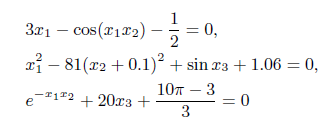

f = @(x)[3 * x(1) + cos(x(1) * x(2)) - 1 / 2; 
         x(1)^2 - 81 * (x(2) + 0.1)^2 + sin(x(3)) + 1.06;
         exp(-x(1) * x(2)) + 20 * x(3) + (10 * pi - 3) / 3];
fd = @(x)[3, x(3) * sin(x(2) * x(3)), x(2) * sin(x(2) * x(3));
          2 * x(1), -162 * (x(2) + 0.1), cos(x(3));
          -x(2) * exp(-x(1) * x(2)), -x(1) * exp(-x(1) * x(2)), 20];

x0 = [0.1; 0.1; -0.1];

% Metoda lui Newton:
[z1, ni1] = Newton2(f, fd, x0, 1E-9);
fprintf("Metoda lui Newton:");

Metoda lui Newton:

fprintf("x1 = %f, x2 = %f, x3 = %f", z1);

x1 = -0.166666, x2 = -0.014807, x3 = -0.523476

fprintf("Numărul de iterații efectuate: %d", ni1);

Numărul de iterații efectuate: 6


% Metoda aproximațiilor succesive:
[z2, ni2] = SuccesiveApprox(f, fd, x0, 1E-9, 100);
fprintf("Metoda aprpximațiilor succesive:");

Metoda aprpximațiilor succesive:

fprintf("x1 = %f, x2 = %f, x3 = %f", z2);

x1 = -0.166666, x2 = -0.014807, x3 = -0.523476

fprintf("Numărul de iterații efectuate: %d", ni2);

Numărul de iterații efectuate: 31

PROBLEME PRACTICE

P1. Rezolvați sistemul:

f = @(x)[x(1)^2 + x(2)^2 - 1;
         x(1)^3 - x(2)];
fd = @(x)[2 * x(1), 2 * x(2);
          3 * x(1)^2, -1];

x0 = [1; 1];
[z, ni] = Newton2(f, fd, x0, 1E-9);

fprintf("Rezolvarea sistemului prin metoda lui Newton:");

Rezolvarea sistemului prin metoda lui Newton:

fprintf("x = %f, y = %f", z);

x = 0.826031, y = 0.563624

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 5

P2. Rezolvați numeric sistemul, utilizând metoda lui Newton și metoda aproximațiilor succesive.

f = @(x)[9 * x(1)^2 + 36 * x(2)^2 + 4 * x(3)^2 - 36;
         x(1)^2 - 2 * x(2)^2 - 20 * x(3);
         x(1)^2 - x(2)^2 + x(3)^2];
fd = @(x)[18 * x(1) + 36 * x(2)^2 + 4 * x(3)^2, 9 * x(1)^2 + 72 * x(2) + 4 * x(3)^2, 9 * x(1)^2 + 36 * x(2)^2 + 8 * x(3);
          2 * x(1) - 2 * x(2)^2 - 20 * x(3), x(1)^2 - 4 * x(2) - 20 * x(3), x(1)^2 - 2 * x(2)^2 - 20;
          2 * x(1) - x(2)^2 + x(3)^2, x(1)^2 - 2 * x(2) + x(3)^2, x(1)^2 - x(2)^2 + 2 * x(3)];

x0 = [1, 1, 0];

% Newton:
[z, ni]=Newton2(f, fd, x0, 1E-9, 100);
fprintf("Prin metoda lui Newton:");

Prin metoda lui Newton:

fprintf("x = %f, y = %f, z = %f", z);

x = 0.946667, y = 0.946667, z = -0.040000

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 1


% Aproximări succesive:
[z, ni] = SuccesiveApprox(f, fd, x0, 1E-9, 100);
fprintf("Prin metoda aproximărilor succesive:");

Prin metoda aproximărilor succesive:

disp(z);

    0.8936    0.8936   -0.1064
    0.8945    0.8945   -0.1055
   -0.0401   -0.0401   -1.0401



fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 92